% Main File to generate Baseline Model Figures 10-11
close all; clear; clc

load ICs_baseline
load baseline_parameter_inputs

% ========================================================================
%  START: EXPERIMENTAL CONFIGURATION BLOCK
% ========================================================================

% --- 1. SELECT WHICH MODEL TO RUN ---
% 0 = Baseline (Isogenic Control)
% 1 = Model 1 (IKr Defect Only)
% 2 = Model 2 (IKr + INa,L)
% 3 = Model 3 (IKr + ICa,P)
% 4 = Model 4 (All Three Defects)
model_to_run = 4; % <--- CHANGE THIS NUMBER TO SELECT YOUR EXPERIMENT

% --- 2. Define Parameter Indices ---
g_Kr_index = 7;   % Conductance of IKr
g_Na_index = 40;  % Conductance of INa (proxy for late current)
p_CaL_index = 30; % Permeability of ICaL (for persistent current)

% --- 3. Apply Modifications Based on Selection ---
modified_params = baseline_parameter_inputs; % Start with the baseline

if model_to_run == 1
    plot_title = 'Model 1: IKr Defect Only';
    % Apply 72.5% IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    
elseif model_to_run == 2
    plot_title = 'Model 2: IKr + INa,L';
    % Apply IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    % Apply 2.31-fold INa,L increase
    modified_params(g_Na_index) = modified_params(g_Na_index) * 2.31;
    
elseif model_to_run == 3
    plot_title = 'Model 3: IKr + ICa,P';
    % Apply IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    % Apply 2.29-fold ICa,P increase
    modified_params(p_CaL_index) = modified_params(p_CaL_index) * 2.29;
    
elseif model_to_run == 4
    plot_title = 'Model 4: All Three Defects';
    % Apply all three modifications
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    modified_params(g_Na_index) = modified_params(g_Na_index) * 2.31;
    modified_params(p_CaL_index) = modified_params(p_CaL_index) * 2.29;
    
else % Default to baseline if model_to_run is 0 or any other number
    plot_title = 'Baseline Model (Isogenic Control)';
end

% Overwrite the original variable with our modified one for the simulation
baseline_parameter_inputs = modified_params;
% ========================================================================
%  END: CONFIGURATION BLOCK
% ========================================================================

## Run iPSC_function

options = odeset('MaxStep',1,'InitialStep',2e-2);
run_time=3e3;
[Time, values] = ode15s(@ipsc_function,[0, run_time],Y_init, options, baseline_parameter_inputs);
Cai=values(:,3);
Vm=values(:,1);

## Calculate select current traces:

INaCa = zeros(size(Time));
IpCa = zeros(size(Time));
Iup = zeros(size(Time));
for i= 1:size(values,1)
    [~, update_step_i] =  ipsc_function(Time(i), values(i,:),  baseline_parameter_inputs);
    INaCa(i) = update_step_i(8);
    IpCa(i) = update_step_i(9);
    Iup(i) = update_step_i(14);
end

## Figure 10A & 10C: Calcium Flux analysis and Calcium Transient Trace

%ca_analysis( Time, Iup, INaCa, IpCa, Cai, plot_title )

## Figure 11A: action potential trace for baseline model

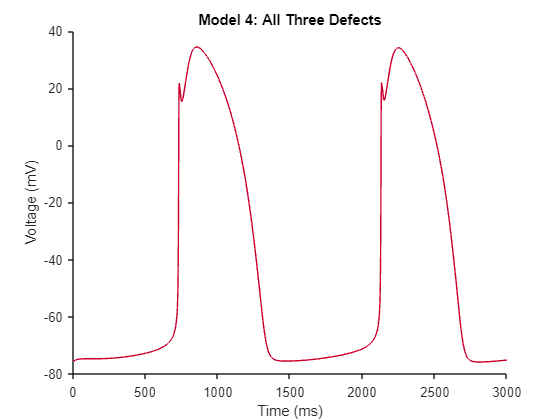

figure,set(gcf,'color','w')
plot(Time, Vm,'Color', [.8 0 .18]);
set(gca,'box','off','tickdir','out')
ylabel('Voltage (mV)');
xlabel('Time (ms)')
title(plot_title)

## Figure 10A & 10C: Calcium Flux analysis and Calcium Transient Trace

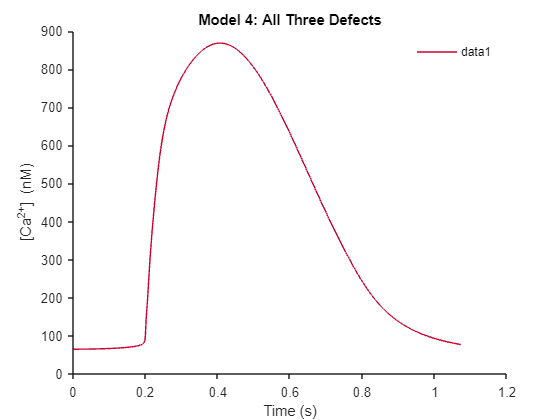

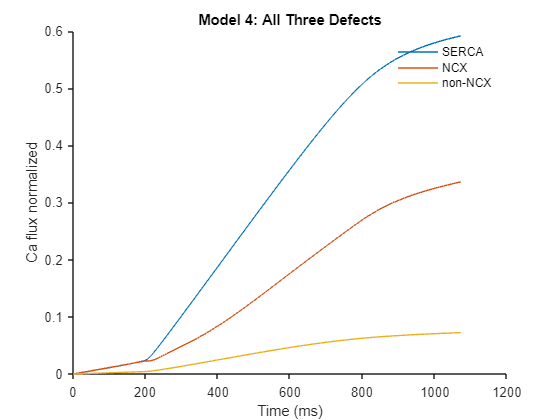

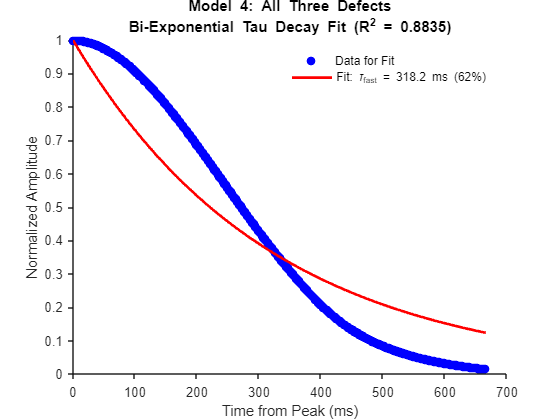

ca_results = ca_analysis( Time, Iup, INaCa, IpCa, Cai, plot_title );

## ========================================================================

fprintf('\n\n--- DATA TABLES FOR: %s ---\n', plot_title);



--- DATA TABLES FOR: Model 4: All Three Defects ---



% --- Display Calcium and Flux Tables (from ca_analysis) ---
fprintf('\n## Table 1: Calcium Transient Morphology ##\n');


## Table 1: Calcium Transient Morphology ##


fprintf('%-30s | %-10.2f\n', 'Peak [Ca²⁺] (nM)', ca_results.peak_ca_nM);

Peak [Ca²⁺] (nM)               | 868.20    


fprintf('%-30s | %-10.2f\n', 'Diastolic [Ca²⁺] (nM)', ca_results.diastolic_ca_nM);

Diastolic [Ca²⁺] (nM)          | 65.09     


fprintf('%-30s | %-10.2f\n', 'Time to Peak (ms)', ca_results.ttp_ms);

Time to Peak (ms)              | 205.51    


fprintf('%-30s | %-10.2f\n', 'Tau Decay Fast (ms)', ca_results.tau_fast_ms);

Tau Decay Fast (ms)            | 318.17    


fprintf('%-30s | %-10.2f\n', 'Tau Decay Slow (ms)', ca_results.tau_slow_ms);

Tau Decay Slow (ms)            | 318.37    


fprintf('%-30s | %-10.2f\n', 'R^2 Tau Decay', ca_results.tau_decay_r_squared);

R^2 Tau Decay                  | 0.88      



fprintf('\n## Table 2: %% Contribution of Calcium Flux ##\n');


## Table 2: % Contribution of Calcium Flux ##


fprintf('%-30s | %-10.1f%%\n', 'SERCA', ca_results.pct_serca);

SERCA                          | 59.2      %


fprintf('%-30s | %-10.1f%%\n', 'NCX', ca_results.pct_ncx);

NCX                            | 33.6      %


fprintf('%-30s | %-10.1f%%\n', 'Non-NCX (I_pCa)', ca_results.pct_ipca);

Non-NCX (I_pCa)                | 7.2       %


## Calculate and Display AP Morphology Table

    % --- C. NEW: Match variable names ---
    % Assign the loaded data to the variable names our functions expect.
    voltage = Vm;   % Assign data from 'Vm' to 'voltage'
    time = Time;    % Assign data from 'Time' to 'time'
    clear Vm Time;  % Good practice to clear the original variables
    
    % --- D. Run the analysis by CALLING the functions ---
    disp('Starting analysis...');

Starting analysis...


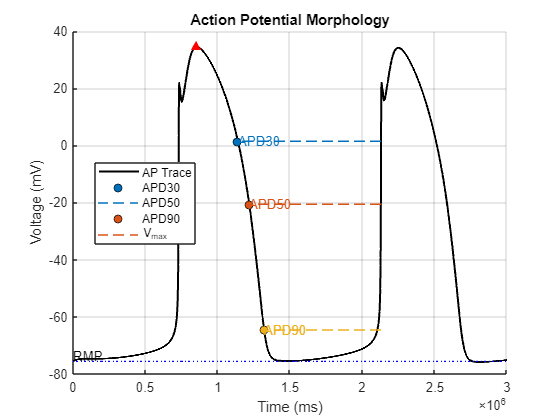

    
    results = CalculateAPMorphology(time, voltage); % 1. Perform calculations
    DisplayAPMorphology(time, voltage, results);     % 2. Create the plot

    DisplayAPMorphologyTable(results);               % 3. Show the results table


--- Action Potential Morphology ---
Parameter         Value Units   
-----------------------------------
RMP              -75.59 mV      
APA              110.00 mV      
Vmax              34.41 mV      
dV/dt max          0.02 V/s     
APD30           -988.69 ms      
APD50           -910.83 ms      
APD90           -807.75 ms      



    
    disp('Analysis complete.');

Analysis complete.


function results = CalculateAPMorphology(time, voltage)
    % Calculates action potential morphology parameters using linear interpolation.

    % --- Standard Calculations ---
    [V_max, idx_max] = max(voltage);
    RMP = mean(voltage(1:10)); 
    APA = V_max - RMP;
    t_peak = time(idx_max);
    
    % --- Max Upstroke Velocity (dV/dt) ---
    dVdt = diff(voltage) ./ diff(time);
    [dVdt_max, idx_dVdt_max] = max(dVdt); % CHANGED: Get the index of dVdt_max
    
    % --- NEW: Define t_depol ---
    t_depol = time(idx_dVdt_max); % CHANGED: This is the true start time for APD calculation

    % --- APD Calculations using Linear Interpolation ---
    repol_phase_time = time(idx_max:end);
    repol_phase_voltage = voltage(idx_max:end);
    
    apd_levels = [30, 50, 90]; 
    
    % Initialize storage
    results.t_rep = zeros(length(apd_levels), 1);
    results.v_rep = zeros(length(apd_levels), 1);
    
    for i = 1:length(apd_levels)
        level = apd_levels(i);
        V_rep_target = V_max - (level/100) * APA;
        
        % Find the index where voltage first drops BELOW the target
        idx2_repol = find(repol_phase_voltage < V_rep_target, 1, 'first');
        
        if ~isempty(idx2_repol) && idx2_repol > 1
            % Get the two points that bracket our target voltage
            t1 = repol_phase_time(idx2_repol - 1);
            v1 = repol_phase_voltage(idx2_repol - 1);
            t2 = repol_phase_time(idx2_repol);
            v2 = repol_phase_voltage(idx2_repol);
            
            % Interpolate the exact time
            t_interpolated = interpolate_time(t1, v1, t2, v2, V_rep_target);
            
            % --- Store results ---
            % CHANGED: Calculate APD from t_depol, not t_peak
            results.(['APD' num2str(level)]) = (t_interpolated - t_depol); % in ms
            results.t_rep(i) = t_interpolated;
            results.v_rep(i) = V_rep_target;
        else
            % Handle cases where repolarization doesn't reach the level
            results.(['APD' num2str(level)]) = NaN;
            results.t_rep(i) = NaN;
            results.v_rep(i) = NaN;
        end
    end
    
    % --- Store other results ---
    results.RMP = RMP;
    results.APA = APA;
    results.V_max = V_max;
    results.t_peak = t_peak;
    results.t_depol = t_depol; % CHANGED: Store t_depol for plotting
    results.dVdt_max = dVdt_max;

end

% --- Helper function for linear interpolation (unchanged) ---
function t_interp = interpolate_time(t1, v1, t2, v2, v_target)
    t_interp = t1 + (v_target - v1) * (t2 - t1) / (v2 - v1);
end


function DisplayAPMorphology(time, voltage, results)
    % Displays the action potential and overlays the calculated morphology parameters.
    
    figure;
    hold on;
    
    % Plot the main AP trace
    plot(time * 1000, voltage, 'k-', 'LineWidth', 1.5);
    title('Action Potential Morphology');
    xlabel('Time (ms)');
    ylabel('Voltage (mV)');
    grid on;
    
    % --- Plot Interpolated APD Markers and Lines ---
    apd_levels = [30, 50, 90];
    colors = lines(length(apd_levels));
    
    for i = 1:length(apd_levels)
        t_rep_val = results.t_rep(i);
        v_rep_val = results.v_rep(i);
        
        if ~isnan(t_rep_val)
            % Plot a marker at the exact interpolated point
            plot(t_rep_val * 1000, v_rep_val, 'o', 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k');
            
            % --- CHANGED: Plot horizontal line from t_depol to t_rep ---
            line([results.t_depol, t_rep_val] * 1000, [v_rep_val, v_rep_val], ...
                 'Color', colors(i,:), 'LineStyle', '--');
            
            % Add a text label
            text(t_rep_val * 1000 + 5, v_rep_val, ['APD' num2str(apd_levels(i))], 'Color', colors(i,:));
        end
    end
    
    % --- Plot other features ---
    % Mark the peak voltage
    plot(results.t_peak * 1000, results.V_max, 'r^', 'MarkerFaceColor', 'r');
    
    % Mark the RMP
    line([time(1), time(end)]*1000, [results.RMP, results.RMP], 'Color', 'b', 'LineStyle', ':');
    text(time(5)*1000, results.RMP + 2, 'RMP');
    
    hold off;
    legend('AP Trace', 'APD30', 'APD50', 'APD90', 'V_{max}', 'Location', 'best');
end



function DisplayAPMorphologyTable(results)
    % Displays the calculated AP morphology parameters in a formatted table.
    
    % Create a header for the table
    fprintf('\n--- Action Potential Morphology ---\n');
    fprintf('===================================\n');
    fprintf('%-12s %10s %-8s\n', 'Parameter', 'Value', 'Units');
    fprintf('-----------------------------------\n');
    
    % Populate the table with data from the results struct
    fprintf('%-12s %10.2f %-8s\n', 'RMP', results.RMP, 'mV');
    fprintf('%-12s %10.2f %-8s\n', 'APA', results.APA, 'mV');
    fprintf('%-12s %10.2f %-8s\n', 'Vmax', results.V_max, 'mV');
    fprintf('%-12s %10.2f %-8s\n', 'dV/dt max', results.dVdt_max / 1000, 'V/s');
    fprintf('%-12s %10.2f %-8s\n', 'APD30', results.APD30, 'ms');
    fprintf('%-12s %10.2f %-8s\n', 'APD50', results.APD50, 'ms');
    fprintf('%-12s %10.2f %-8s\n', 'APD90', results.APD90, 'ms');
    
    fprintf('===================================\n\n');
end
